# Problèmatique

## Calculs

clc
clear all
close all

warning('off','all')

%Matrices de départ 
A = [-0.018223 -0.088571 -9.78  0.0000;
     -0.003038 -1.256300  0.00  1.0000;
      0.000000  0.000000  0.00  1.0000;
      0.061700   -28.075  0.00 -4.5937];
B = [0.00  1.1962;
     0.00 -0.0012;
     0.00  0.0000;
     7.84 -4.0500];
C = [1  00.000  00.000 00.000;
     0  57.296  00.000 00.000;
     0  00.000  57.296 00.000;
     0  00.000  00.000 57.296;
     0 -57.296 57.296 00.000];
D = [0 0;
     0 0;
     0 0;
     0 0;
     0 0];

%On sort les numérateur et dénominateurs des fonctions avec ABCD

%𝑢 = [𝛿𝑐 𝑎𝑝𝑟𝑜𝑝]^T
%Y = [𝑣 𝛼 𝜃 𝑞 𝛾]^T

%Num1 et Den1 sont par rapport à angle gouvernail (delta)
[Num1, Den1] = ss2tf(A,B,C,D,1);
%Num2 et Den2 sont par rapport à fraction pousser max (gamma)
[Num2, Den2] = ss2tf(A,B,C,D,2);

%5 premières fonctions est l'angle de gouvernail en fonction de [𝑣 𝛼 𝜃 𝑞 𝛾]
%6 à 10 sont la fraction de poussermax en fonction de [𝑣 𝛼 𝜃 𝑞 𝛾]

%On calcul le poids des pôles
[r1, p1, k1] = residue(Num1(1,:), Den1);
[r2, p2, k2] = residue(Num1(2,:), Den1);
[r3, p3, k3] = residue(Num1(3,:), Den1);
[r4, p4, k4] = residue(Num1(4,:), Den1);
[r5, p5, k5] = residue(Num1(5,:), Den1);
[r6, p6, k6] = residue(Num2(1,:), Den2);
[r7, p7, k7] = residue(Num2(2,:), Den2);
[r8, p8, k8] = residue(Num2(3,:), Den2);
[r9, p9, k9] = residue(Num2(4,:), Den2);
[r10, p10, k10] = residue(Num2(5,:), Den2);

%On calcul les poids
poids = [];
poids(:,1) = abs(r1)./abs(real(p1));% 3 et 4 de beaucoup
poids(:,2) = abs(r2)./abs(real(p2));%3 et 4 
poids(:,3) = abs(r3)./abs(real(p3));%3 et 4 de beaucoup
poids(:,4) = abs(r4)./abs(real(p4));%3 et 4
poids(:,5) = abs(r5)./abs(real(p5));%3 et 4 de beaucoup
poids(:,6) = abs(r6)./abs(real(p6));%3 et 4 de beaucoup
poids(:,7) = abs(r7)./abs(real(p7));%3 et 4
poids(:,8) = abs(r8)./abs(real(p8));%3 et 4 de beaucoup
poids(:,9) = abs(r9)./abs(real(p9));%3 et 4
poids(:,10) = abs(r10)./abs(real(p10));%3 et 4 de beaucoup

%On crée les nouvelles fonction de transfert avec les poids dominant
sys1_1 = tf([r1(1)], [1 -p1(1)]);
sys1_2 = tf([r1(2)], [1 -p1(2)]);
sys1_3 = tf([r1(3)], [1 -p1(3)]);
sys1_4 = tf([r1(4)], [1 -p1(4)]);

sys2_1 = tf([r2(1)], [1 -p2(1)]);
sys2_2 = tf([r2(2)], [1 -p2(2)]);
sys2_3 = tf([r2(3)], [1 -p2(3)]);
sys2_4 = tf([r2(4)], [1 -p2(4)]);

sys3_1 = tf([r3(1)], [1 -p3(1)]);
sys3_2 = tf([r3(2)], [1 -p3(2)]);
sys3_3 = tf([r3(3)], [1 -p3(3)]);
sys3_4 = tf([r3(4)], [1 -p3(4)]);

sys4_1 = tf([r4(1)], [1 -p4(1)]);
sys4_2 = tf([r4(2)], [1 -p4(2)]);
sys4_3 = tf([r4(3)], [1 -p4(3)]);
sys4_4 = tf([r4(4)], [1 -p4(4)]);

sys5_1 = tf([r5(1)], [1 -p5(1)]);
sys5_2 = tf([r5(2)], [1 -p5(2)]);
sys5_3 = tf([r5(3)], [1 -p5(3)]);
sys5_4 = tf([r5(4)], [1 -p5(4)]);

sys6_1 = tf([r6(1)], [1 -p6(1)]);
sys6_2 = tf([r6(2)], [1 -p6(2)]);
sys6_3 = tf([r6(3)], [1 -p6(3)]);
sys6_4 = tf([r6(4)], [1 -p6(4)]);

sys7_1 = tf([r7(1)], [1 -p7(1)]);
sys7_2 = tf([r7(2)], [1 -p7(2)]);
sys7_3 = tf([r7(3)], [1 -p7(3)]);
sys7_4 = tf([r7(4)], [1 -p7(4)]);

sys8_1 = tf([r8(1)], [1 -p8(1)]);
sys8_2 = tf([r8(2)], [1 -p8(2)]);
sys8_3 = tf([r8(3)], [1 -p8(3)]);
sys8_4 = tf([r8(4)], [1 -p8(4)]);

sys9_1 = tf([r9(1)], [1 -p9(1)]);
sys9_2 = tf([r9(2)], [1 -p9(2)]);
sys9_3 = tf([r9(3)], [1 -p9(3)]);
sys9_4 = tf([r9(4)], [1 -p9(4)]);

sys10_1 = tf([r10(1)], [1 -p10(1)]);
sys10_2 = tf([r10(2)], [1 -p10(2)]);
sys10_3 = tf([r10(3)], [1 -p10(3)]);
sys10_4 = tf([r10(4)], [1 -p10(4)]);

%Celle qui nous interesse le plus c'est F(2,1)
%On remplace les fonction de transfert par les nouvelles
FT = [sys1_3+sys1_4 sys2_3+sys2_4 sys3_3+sys3_4 sys4_3+sys4_4 sys5_3+sys5_4;
      sys6_3+sys6_4 sys7_3+sys7_4 sys8_3+sys8_4 sys9_3+sys9_4 sys10_3+sys10_4];
FT2 = [sys1_1+sys1_2 sys2_1+sys2_2 sys3_1+sys3_2 sys4_1+sys4_2 sys5_1+sys5_2;
       sys6_1+sys6_2 sys7_1+sys7_2 sys8_1+sys8_2 sys9_1+sys9_2 sys10_1+sys10_2];

%On calcule les coefficient des fonctions de transfert
[num1, den1] = tfdata(FT(1,1), 'v');
[num2, den2] = tfdata(FT(1,2), 'v');
[num3, den3] = tfdata(FT(1,3), 'v');
[num4, den4] = tfdata(FT(1,4), 'v');
[num5, den5] = tfdata(FT(1,5), 'v');
[num6, den6] = tfdata(FT(2,1), 'v');
[num7, den7] = tfdata(FT(2,2), 'v');
[num8, den8] = tfdata(FT(2,3), 'v');
[num9, den9] = tfdata(FT(2,4), 'v');
[num10, den10] = tfdata(FT(2,5), 'v');

[num_mode2, den_mode2] = tfdata(FT2(2,1), 'v');


%Calcul des fréquences
W_n = [sqrt(den1(3)) sqrt(den2(3)) sqrt(den3(3)) sqrt(den4(3)) sqrt(den5(3));
       sqrt(den6(3)) sqrt(den7(3)) sqrt(den8(3)) sqrt(den9(3)) sqrt(den10(3))];
%Calcul Wn uniquement V en fonction de a_prop
W_n_mode2 = sqrt(den_mode2(3));

%Calcul des zeta
Zeta = [den1(2)/(2*W_n(1,1)) den2(2)/(2*W_n(1,2)) den3(2)/(2*W_n(1,3)) den4(2)/(2*W_n(1,4)) den5(2)/(2*W_n(1,5));
        den6(2)/(2*W_n(2,1)) den7(2)/(2*W_n(2,2)) den8(2)/(2*W_n(2,3)) den9(2)/(2*W_n(2,4)) den10(2)/(2*W_n(2,5))];
%Calcul Zeta uniquement V en fonction de a_prop
Zeta_mode2 = den_mode2(2)/(2*W_n_mode2);

## Graphiques des Steps

%On veut l'information du step on affiche seulement V en fonction de a_prop
% step(FT(1,1));
% step(FT(1,2));
% step(FT(1,3));
% step(FT(1,4));
% step(FT(1,5));
% step(FT(2,1));
% step(FT(2,2));
% step(FT(2,3));
% step(FT(2,4));
% step(FT(2,5));

## Info des Steps

info1 = stepinfo(FT(1,1));
info2 = stepinfo(FT(1,2));
info3 = stepinfo(FT(1,3));
info4 = stepinfo(FT(1,4));
info5 = stepinfo(FT(1,5));
info6 = stepinfo(FT(2,1));
info7 = stepinfo(FT(2,2));
info8 = stepinfo(FT(2,3));
info9 = stepinfo(FT(2,4));
info10 = stepinfo(FT(2,5));

%info non phugoide uniquement de V en fonction de a_prop
info_mode2 = stepinfo(FT2(2,1));

%Information Matrice ligne 1 = tout ce qui est par rapport a l'angle
%Information Matrice ligne 2 = tout ce qui est par rapport à la pousser max
SettlingTime = [info1.SettlingTime info2.SettlingTime info3.SettlingTime info4.SettlingTime info5.SettlingTime;
                info6.SettlingTime info7.SettlingTime info8.SettlingTime info9.SettlingTime info10.SettlingTime];
PeakTime = [info1.PeakTime info2.PeakTime info3.PeakTime info4.PeakTime info5.PeakTime;
            info6.PeakTime info7.PeakTime info8.PeakTime info9.PeakTime info10.PeakTime];
OverShoot = [info1.Overshoot info2.Overshoot info3.Overshoot info4.Overshoot info5.Overshoot;
             info6.Overshoot info7.Overshoot info8.Overshoot info9.Overshoot info10.Overshoot];


## Calcul à la main des steps

%Calcul à la main phugoide
Ts_mode1 = 4/(W_n(2,1)*Zeta(2,1));
W_a_mode1 = W_n(2,1)*sqrt(1-Zeta(2,1)^2);
Tp_mode1 = pi/(W_a_mode1);
Mp_mode1 = 100*exp(-pi/tan(acos(Zeta(2,1))));

%Calcul à la main non-phugoide
Ts_mode2 = 4/(W_n_mode2*Zeta_mode2);
W_a_mode2 = W_n_mode2*sqrt(1-Zeta_mode2^2);
Tp_mode2 = pi/(W_a_mode2);
Mp_mode2 = 100*exp(-pi/tan(acos(Zeta_mode2)));

## a) Caractéristiques dynamiques

%On sait qu'on chercher V en fonction de a_prop donc c'est FT(2,1) donc les informations (2,1)
disp("------------------------A------------------------");

------------------------A------------------------


% disp("Calcul en utilisant Step Info")
% %Phugoide stepinfo
% String = "Temps du premier pic Phugoide (StepInfo)= " + string(PeakTime(2,1));
% disp(String);
% String = "Dépassement maximale Phugoide (StepInfo)= " + string(OverShoot(2,1));
% disp(String);
% String = "Temps stabilisation Phugoide (StepInfo)= " + string(SettlingTime(2,1));
% disp(String);
% String = "Facteur Amortissement (Zeta) Phugoide (StepInfo)= " + string(Zeta(2,1));
% disp(String);
% %Non phugoide stepinfo
% String = "Temps du premier pic Non-Phugoide (StepInfo)= " + string(info_mode2.PeakTime);
% disp(String);
% String = "Dépassement maximale Non-Phugoide (StepInfo)= " + string(info_mode2.Overshoot);
% disp(String);
% String = "Temps stabilisation Non-Phugoide (StepInfo)= " + string(info_mode2.SettlingTime);
% disp(String);
% String = "Facteur Amortissement (Zeta) Non-Phugoide (StepInfo)= " + string(Zeta_mode2);
% disp(String);

disp("Calcul à la main des données")

Calcul à la main des données


disp(" ")

%Phugoide à la main
String = "Temps du premier pic Phugoide (main)= " + string(Tp_mode1);
disp(String);

Temps du premier pic Phugoide (main)= 14.4923


String = "Dépassement maximale Phugoide (main)= " + string(Mp_mode1);
disp(String);

Dépassement maximale Phugoide (main)= 81.565


String = "Temps stabilisation Phugoide (main)= " + string(Ts_mode1);
disp(String);

Temps stabilisation Phugoide (main)= 284.4829


String = "Facteur Amortissement (Zeta) Phugoide (main)= " + string(Zeta(2,1));
disp(String);

Facteur Amortissement (Zeta) Phugoide (main)= 0.064726


String = "Période d'oscillation naturel W_n Phugoide = " + string(W_n(2,1));
disp(String)

Période d'oscillation naturel W_n Phugoide = 0.21723


String = "Période d'oscillation ammorti W_a Phugoide = " + string(W_a_mode1);
disp(String)

Période d'oscillation ammorti W_a Phugoide = 0.21678


disp(" ")

%Non-phugoide à la main
String = "Temps du premier pic Non-Phugoide (main)= " + string(Tp_mode2);
disp(String);

Temps du premier pic Non-Phugoide (main)= 0.62564


String = "Dépassement maximale Non-Phugoide (main)= " + string(Mp_mode2);
disp(String);

Dépassement maximale Non-Phugoide (main)= 16.091


String = "Temps stabilisation Non-Phugoide (main)= " + string(Ts_mode2);
disp(String);

Temps stabilisation Non-Phugoide (main)= 1.3698


String = "Facteur Amortissement (Zeta) Non-Phugoide (main)= " + string(Zeta_mode2);
disp(String);

Facteur Amortissement (Zeta) Non-Phugoide (main)= 0.5027


String = "Période d'oscillation naturel W_n Non-Phugoide = " + string(W_n_mode2);
disp(String)

Période d'oscillation naturel W_n Non-Phugoide = 5.8087


String = "Période d'oscillation ammorti W_a Non-Phugoide = " + string(W_a_mode2);
disp(String)

Période d'oscillation ammorti W_a Non-Phugoide = 5.0214


disp(" ")


String = "Figure 1 : Step response de V en fonction de A_prop (Phugoide)";
disp(String);

Figure 1 : Step response de V en fonction de A_prop (Phugoide)


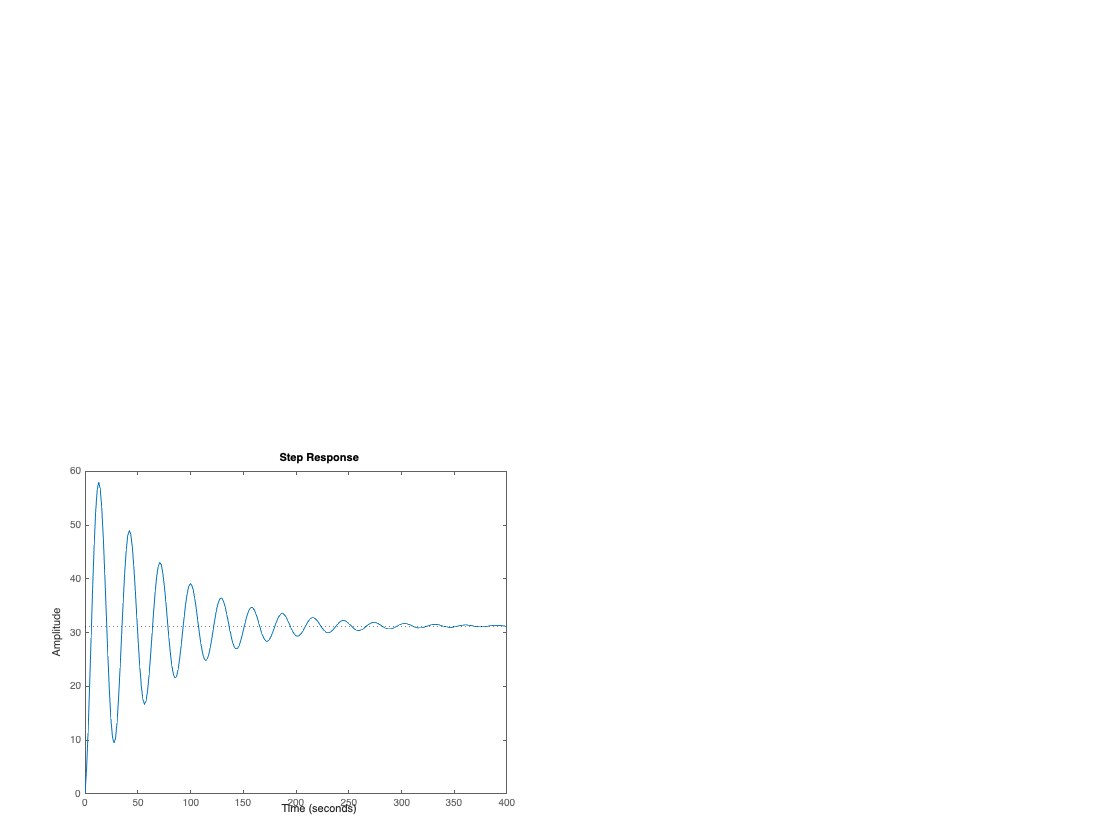

figure;
step(FT(2,1));


String = "Figure 2 : Step response de V en fonction de A_prop (Non-Phugoide)";
disp(String);

Figure 2 : Step response de V en fonction de A_prop (Non-Phugoide)


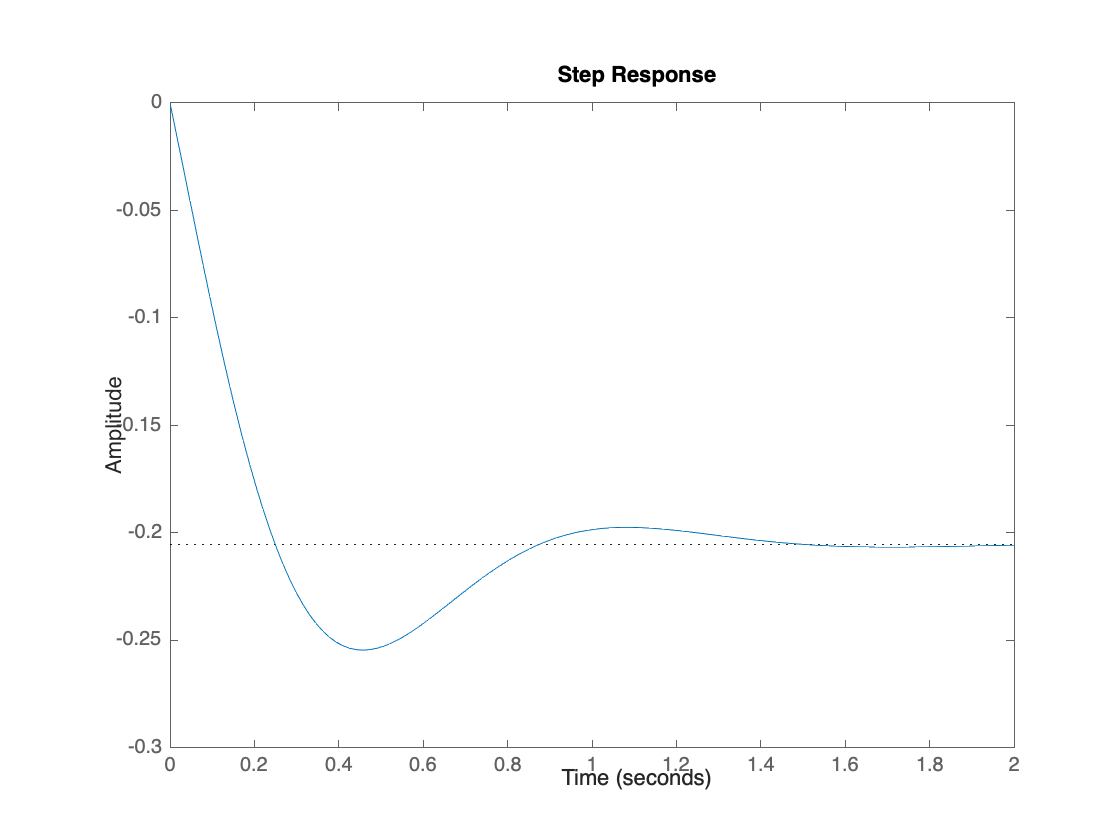

figure;
step(FT2(2,1));

## b) Fonction de transfert à phase non minimale

%On prends toute les valeurs de l'angle de vol en fonction de l'angle du gouvernail 
disp("------------------------B------------------------");

------------------------B------------------------


String = "Figure 3 : Pôles et zéros de le V en fonction de A_prop";
disp(String);

Figure 3 : Pôles et zéros de le V en fonction de A_prop


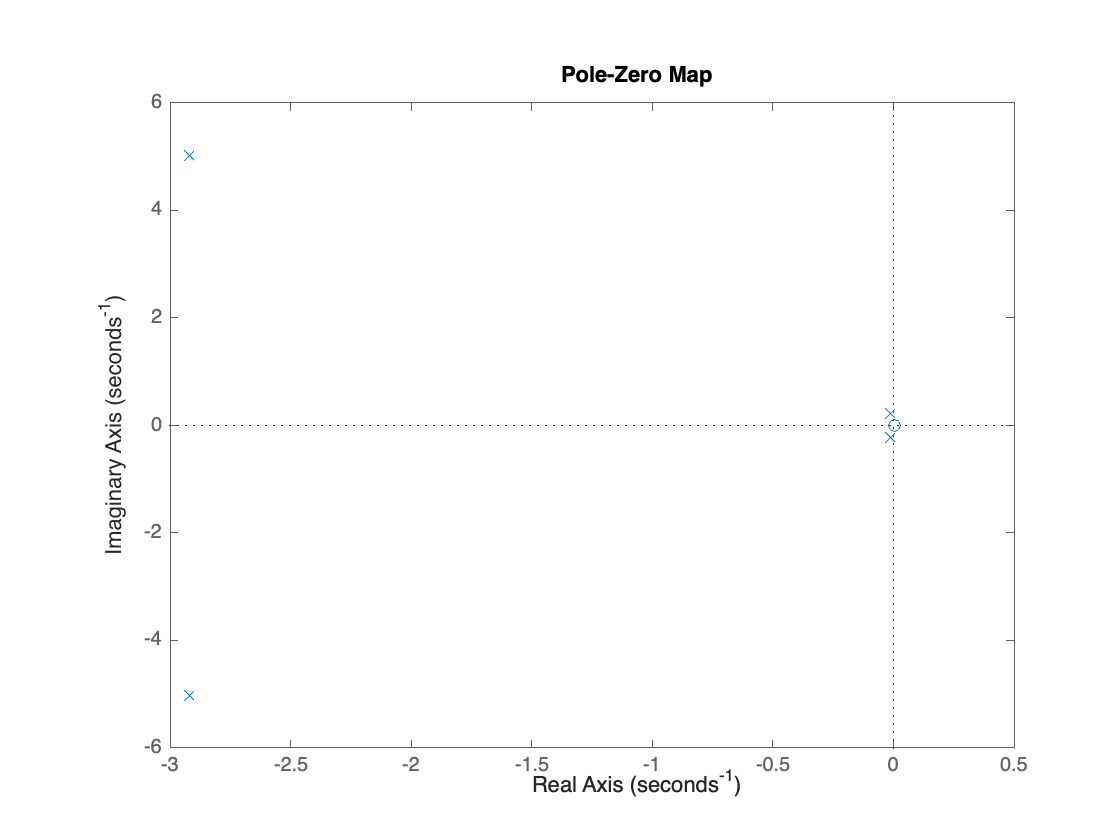

figure;
pzmap(Num1(5,:), Den1);

%Bode de delta gamma
% figure;
% margin(Num1(5,:), Den1);

## c) Lieu des racines fait à la main (Certain calculs fait sur MatLab)

disp("------------------------C------------------------");

------------------------C------------------------



%Fonction de transfert en fonction de la fraction maximale et la vitesse 
FT_Fraction_Vitesse = tf(Num2(1,:), Den2);
String = "Fonction de transfert dy système non réduit V en fonction de A_prop";
disp(String);

Fonction de transfert dy système non réduit V en fonction de A_prop


FT_Fraction_Vitesse

FT_Fraction_Vitesse =
 
     1.196 s^3 + 6.998 s^2 + 80.45 s + 49.43
  ---------------------------------------------
  s^4 + 5.868 s^3 + 33.95 s^2 + 1.224 s + 1.592
 
Continuous-time transfer function.
Model Properties



%Étape 2
Zero = roots(Num2(1,:));
Pole = roots(Den2);

String = "Zeros = ";
disp(String);

Zeros = 


disp(Zero);

  -2.6017 + 7.5581i
  -2.6017 - 7.5581i
  -0.6468 + 0.0000i



String = "Pôles = ";
disp(String);

Pôles = 


disp(Pole);

  -2.9201 + 5.0214i
  -2.9201 - 5.0214i
  -0.0141 + 0.2168i
  -0.0141 - 0.2168i




%Étape 8
Angle_P1 =  360 + 180 + (rad2deg(angle(Pole(1)-Zero(1)))+rad2deg(angle(Pole(1)-Zero(2)))+rad2deg(angle(Pole(1)-Zero(3)))) - (rad2deg(angle(Pole(1)-Pole(2)))+rad2deg(angle(Pole(1)-Pole(3)))+rad2deg(angle(Pole(1)-Pole(4))));
Angle_P3 =  180 + (rad2deg(angle(Pole(3)-Zero(1)))+rad2deg(angle(Pole(3)-Zero(2)))+rad2deg(angle(Pole(3)-Zero(3)))) - (rad2deg(angle(Pole(3)-Pole(2)))+rad2deg(angle(Pole(3)-Pole(1)))+rad2deg(angle(Pole(3)-Pole(4))));
Angle_Z1 = -360 + 180 - (rad2deg(angle(Zero(1)-Zero(2)))+rad2deg(angle(Zero(1)-Zero(3)))) + (rad2deg(angle(Zero(1)-Pole(1)))+rad2deg(angle(Zero(1)-Pole(2)))+rad2deg(angle(Zero(1)-Pole(3)))+rad2deg(angle(Zero(1)-Pole(4))));
Angle_Z3 =  180 - (rad2deg(angle(Zero(3)-Zero(1)))+rad2deg(angle(Zero(3)-Zero(2)))) + (rad2deg(angle(Zero(3)-Pole(1)))+rad2deg(angle(Zero(3)-Pole(2)))+rad2deg(angle(Zero(3)-Pole(3)))+rad2deg(angle(Zero(3)-Pole(4))));

p_Fraction_Vitesse = rlocus(FT_Fraction_Vitesse, 1);

%On trace la locus de vitesse en fonction de la fraction de pousser
% figure
% rlocus(FT_Fraction_Vitesse)
% hold on
% plot(real(p_Fraction_Vitesse), imag(p_Fraction_Vitesse), 'x', 'MarkerSize',10) 
% hold on

## d) Trouver le K_v dans le graphique à l'intersection

disp("------------------------D------------------------")

------------------------D------------------------


String = "Figure 4 : Lieu des racines de V en fonction de A_prop (modèle réduit)";
disp(String);

Figure 4 : Lieu des racines de V en fonction de A_prop (modèle réduit)


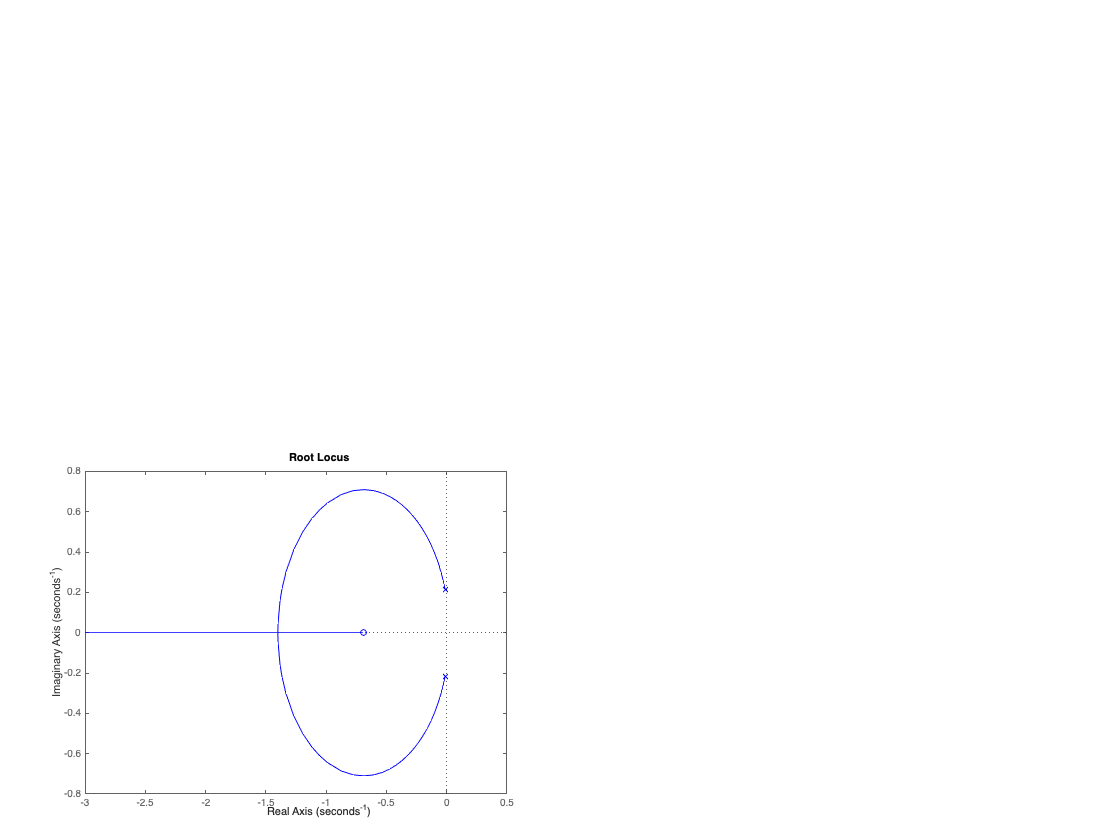

figure;
%Grâce à ce graphique il est possible de voir que le gain à l'intersection est de 1.3
rlocus(FT(2,1), 'blue')

String = "Il est possible de savoir que pour avoir plus stable il faut déplacer le zéro à l'intersection de la courbe entre les deux pôles";
disp(String);

Il est possible de savoir que pour avoir plus stable il faut déplacer le zéro à l'intersection de la courbe entre les deux pôles



String = "Figure 5 : Lieu des racines de V en fonction de A_prop (modèle complet)";
disp(String);

Figure 5 : Lieu des racines de V en fonction de A_prop (modèle complet)


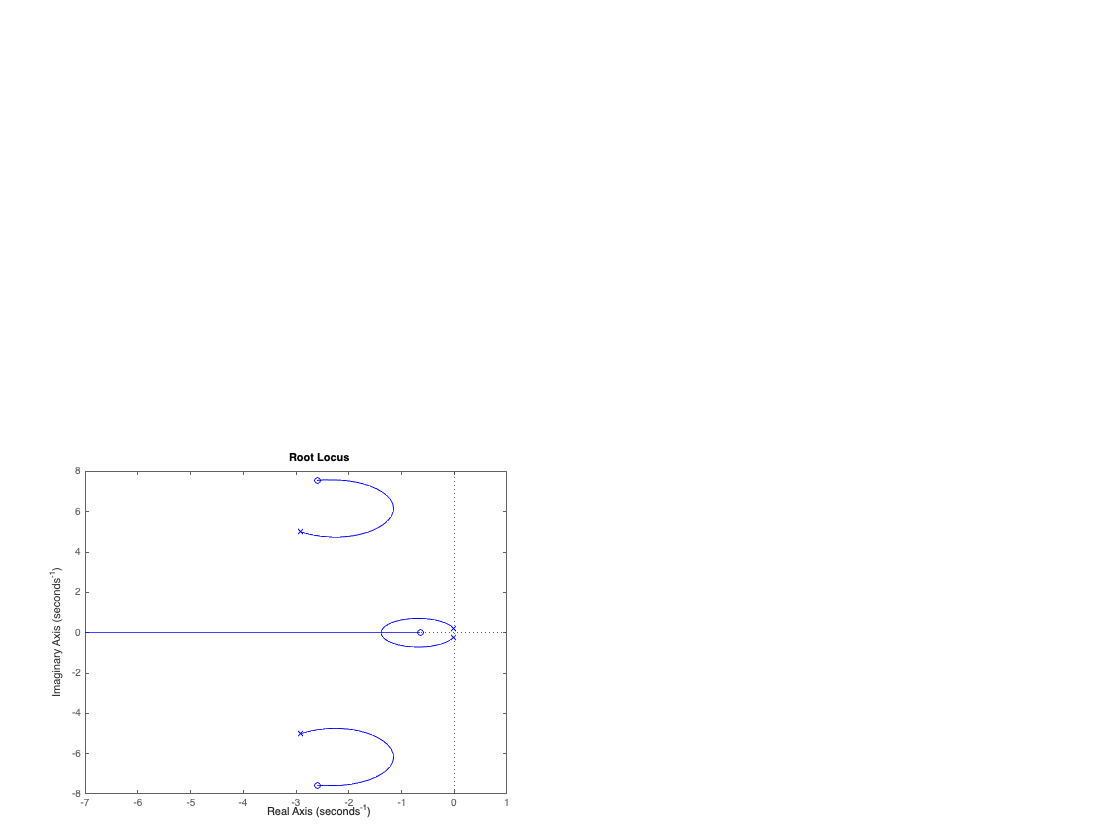

figure;
%Grâce à ce graphique il est possible de voir que le gain à l'intersection est de 1.3
rlocus(Num2(1,:), Den2, 'blue')

## e) Création des nouvelles matrices A1,B1,C1,D1

disp("------------------------E------------------------")

------------------------E------------------------


%On choisi notre range de Kv
Kv = -1.03;

String = "(1) On choisi notre K_v en utilisant l'intersection de la courbe des pôles.";
disp(String);

(1) On choisi notre K_v en utilisant l'intersection de la courbe des pôles.


String = "K_v = " + string(Kv);
disp(String);

K_v = -1.03



%On recrée les nouvelles matrice avec le K_v trouver
A1 = [A(1,1)+B(1,2)*Kv A(1,2) A(1,3) A(1,4);
      A(2,1)+B(2,2)*Kv A(2,2) A(2,3) A(2,4);
      A(3,1)+B(3,2)*Kv A(3,2) A(3,3) A(3,4);
      A(4,1)+B(4,2)*Kv A(4,2) A(4,3) A(4,4)];
B1 = [B(1,1);
      B(2,1);
      B(3,1);
      B(4,1)];
C1 = C;
D1 = [0;
      0;
      0;
      0;
      0];

%On trouve la nouvelle fonction de transfert
[Num3, Den3] = ss2tf(A1,B1,C1,D1);
%V en fonction de fraction de pousser
FT3 = tf(Num3(1,:), Den3);

String = "(2) Calcul des nouvelles matrices A,B,C,D avec le nouveau K_v fonction de transfert = ";
disp(String);

(2) Calcul des nouvelles matrices A,B,C,D avec le nouveau K_v fonction de transfert = 


FT3

FT3 =
 
               -77.37 s - 96.33
  -------------------------------------------
  s^4 + 7.1 s^3 + 41.16 s^2 + 84.09 s + 52.51
 
Continuous-time transfer function.
Model Properties



INFO = stepinfo(FT3);

%On trace la step response
% figure
% step(FT3)
% hold on
% legend("K_v = " + num2str(Kv))

## f) Bode avec A1,B1,C1,D1

%Creation du diagram de Bode de vitesse en fonction de fraction
%Avec réduit
disp("------------------------F------------------------")

------------------------F------------------------


String = "Figure 6 : Vérification des marges avec diagrammes de Bode";
disp(String)

Figure 6 : Vérification des marges avec diagrammes de Bode


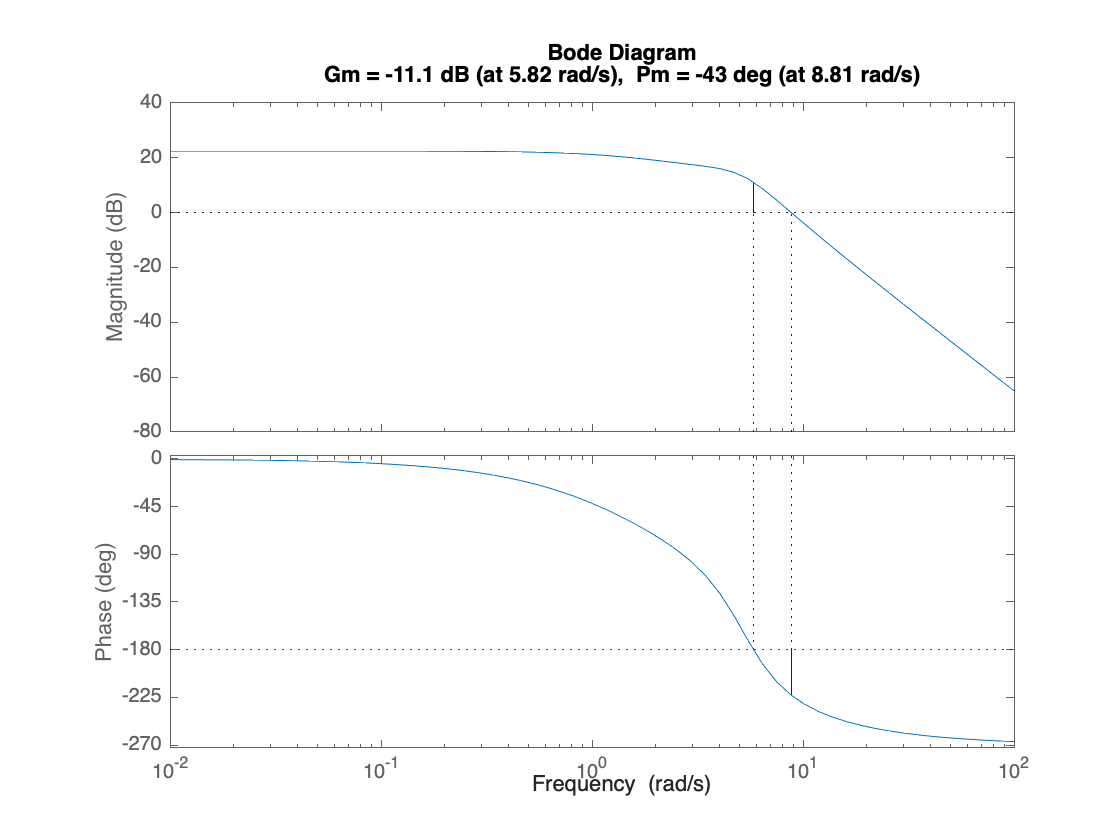


figure;
FT_K_V = tf([Num3(5,:)],[Den3]);
margin(FT_K_V)

String = "On voit que nous sommes correct puisqu'on veut 6dB et 30°";
disp(String)

On voit que nous sommes correct puisqu'on veut 6dB et 30°


## k) Création de la boucle complète

disp("------------------------K------------------------")

------------------------K------------------------


%On trouver K_p grâce au graphique à la figure 5
K_p = 0.186;
[K_lim, ~, ~, ~] = margin(FT_K_V);

String = "(1) K_lim du système = " + string(K_lim);
disp(String);

(1) K_lim du système = 0.27752


String = "(2) Calcul de K_p a été fait en utilisant la Figure 5, en faissant varier jusqu'à ce qu'on trouve dB = 6 et Phase = 30°";
disp(String);

(2) Calcul de K_p a été fait en utilisant la Figure 5, en faissant varier jusqu'à ce qu'on trouve dB = 6 et Phase = 30°


String = "K_p = " + string(K_p);
disp(String);

K_p = 0.186


disp(" ");


%On reprends les valeurs de la section précédente dans des novuelles variables être sur qu'on les perds pas
Num_complet = Num3;
Den_complet = Den3;
FT_complet = tf([Num_complet(5,:)], [Den_complet]);

%Pour le compensateur qui P qui est unquement * K_p
FT_P = K_p*FT_complet;
FT_P_Fermer = feedback(FT_P, 1);

%On trace le nouveau bode avec le nouveau K_p
String = "Figure 7 : Nouveau Bode avec K_p = " + string(K_p);
disp(String);

Figure 7 : Nouveau Bode avec K_p = 0.186


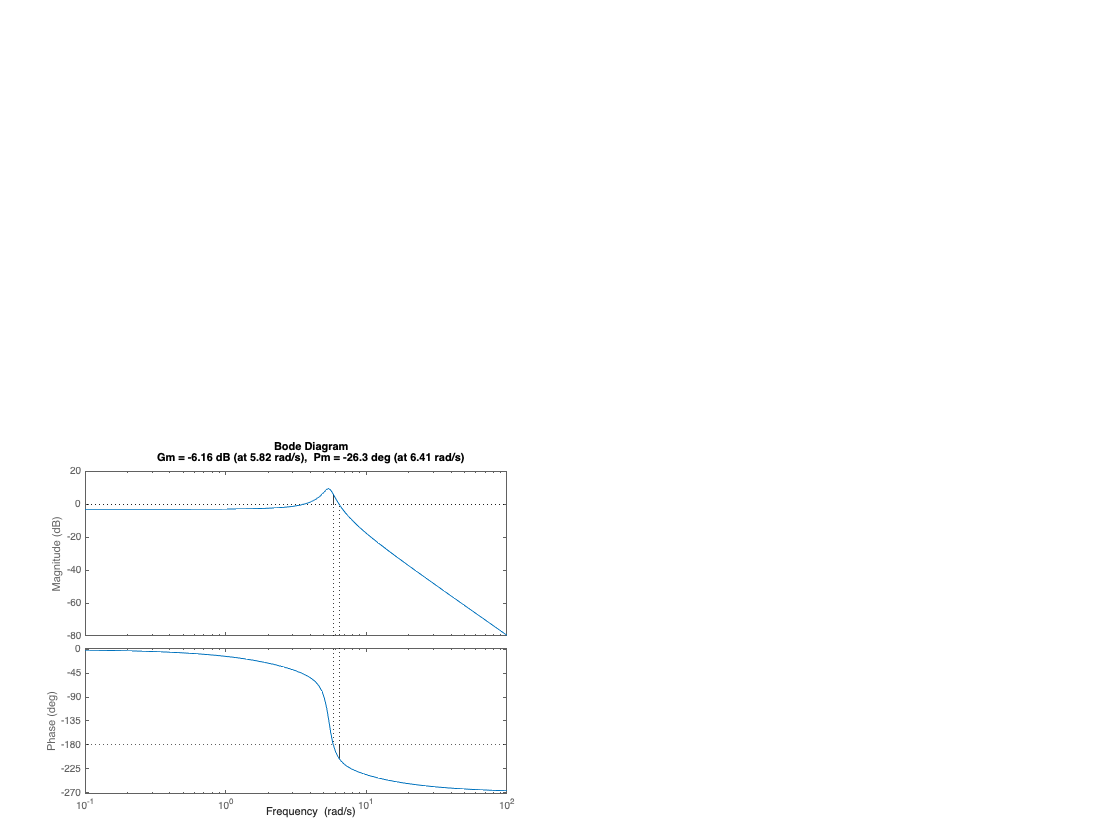

margin(FT_P_Fermer);

String = "Il est possible de voir que notre angle est 30° et que notre gain est de 7.51, les deux conditions sont donc atteint";
disp(String);

Il est possible de voir que notre angle est 30° et que notre gain est de 7.51, les deux conditions sont donc atteint



%Plot de seulement K
% figure
% rlocus(FT_P)
% legend("P")
% figure
% step(FT_P_Fermer)
% legend("P")

%Avec PD
Num_PD = [K_p K_p];
Den_PD = [1];

FT_PD = tf([Num_PD],[Den_PD])*FT_complet;
FT_PD_Fermer = feedback(FT_PD, 1);

% figure
% rlocus(FT_PD)
% legend("PD")
% figure
% step(FT_PD_Fermer)
% legend("PD")

%Avec PI
Num_PI = [K_p K_p];
Den_PI = [1 0];

FT_PI = tf([Num_PI],[Den_PI])*FT_complet;
FT_PI_Fermer = feedback(FT_PI, 1);

% figure
% rlocus(FT_PI)
% legend("PI")
% figure
% step(FT_PI_Fermer)
% legend("PI")

%Avec PID
Num_PID = [K_p K_p K_p];
Den_PID = [1 0];

FT_PID = tf([Num_PID],[Den_PID])*FT_complet;
FT_PID_Fermer = feedback(FT_PID, 1);

% figure
% rlocus(FT_PID)
% legend("PID")
% figure
% step(FT_PID_Fermer)
% legend("PID")